# C. PID Cntroller Design

Objective:

- Implement a PID controller

- understand the influence of each coefficient

- Choose the controller gain by heuristic method (try an error)

To be able to control a system, there must be a feedback loop where sensors are placed to measure the actual response of the sytem, then compared with the input (desired output).

To make sure the response attain the desired performace criteria, a controller need to be added. We recall the usual criteria of performances are:

- Rise time (the shorter the better)

- Steady state error (the smaller the better)

- Overshoot (the smaller the better)

To illustrate the PID implementation, we will be using the same mass spring system, complete with a unity feedback loop (($C\left(s\right)=1$). This is similar to not having a controller. ) and its step response that we recall here:

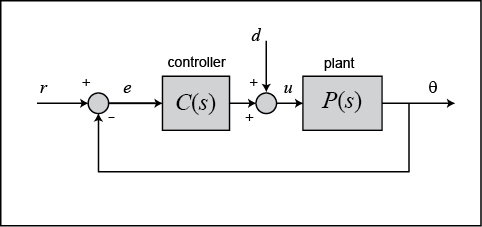

%  slightly modified system parameter
M = 10;         % mass in kg
b = 5;        % viscuous friction in N/m/s^2
k = 1;         % spring elasticy in N/m
s = tf('s');
G_MassSpring = 1/(M*s^2 + b*s + k)  

G_MassSpring =
 
         1
  ----------------
  10 s^2 + 5 s + 1
 
Continuous-time transfer function.



sys_cl = feedback(G_MassSpring,1)   % closed loop TF

sys_cl =
 
         1
  ----------------
  10 s^2 + 5 s + 2
 
Continuous-time transfer function.



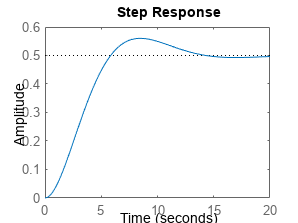

t = 0:0.1:20;
step(sys_cl,t)

The performance criteria are:

% Performance criteria 
y = step(sys_cl,t);
y_ss = y(end)  % Steady-state value is the final value of the response

y_ss = 0.4965

Overshoot = (max(y) - y_ss) / y_ss * 100  % Overshoot as a percentage

Overshoot = 12.8119

% Calculate rise time (time to reach 90% of the steady-state value)
tolerance = 0.10;
idx_rise = find(y >= (1 - tolerance) * y_ss, 1);
rise_time = t(idx_rise)

rise_time = 5

- Steady state: 0.5 m - final value

- Rise time: 5 seconds - times taken to reach 63% of the final value

- Overshoot: 12.8% at 0.55m - the maximum value surpassing the steady state value.

## PID transfer function

PID consists of 3 terms that will be multiplied to the error $e$ (output of the closed loop comparator). The 3 terms are

- Proportional gain, $K_p$

- Integrator gian, $K_i$

- Derivative gain, $K_d$

All together, they can be written as:

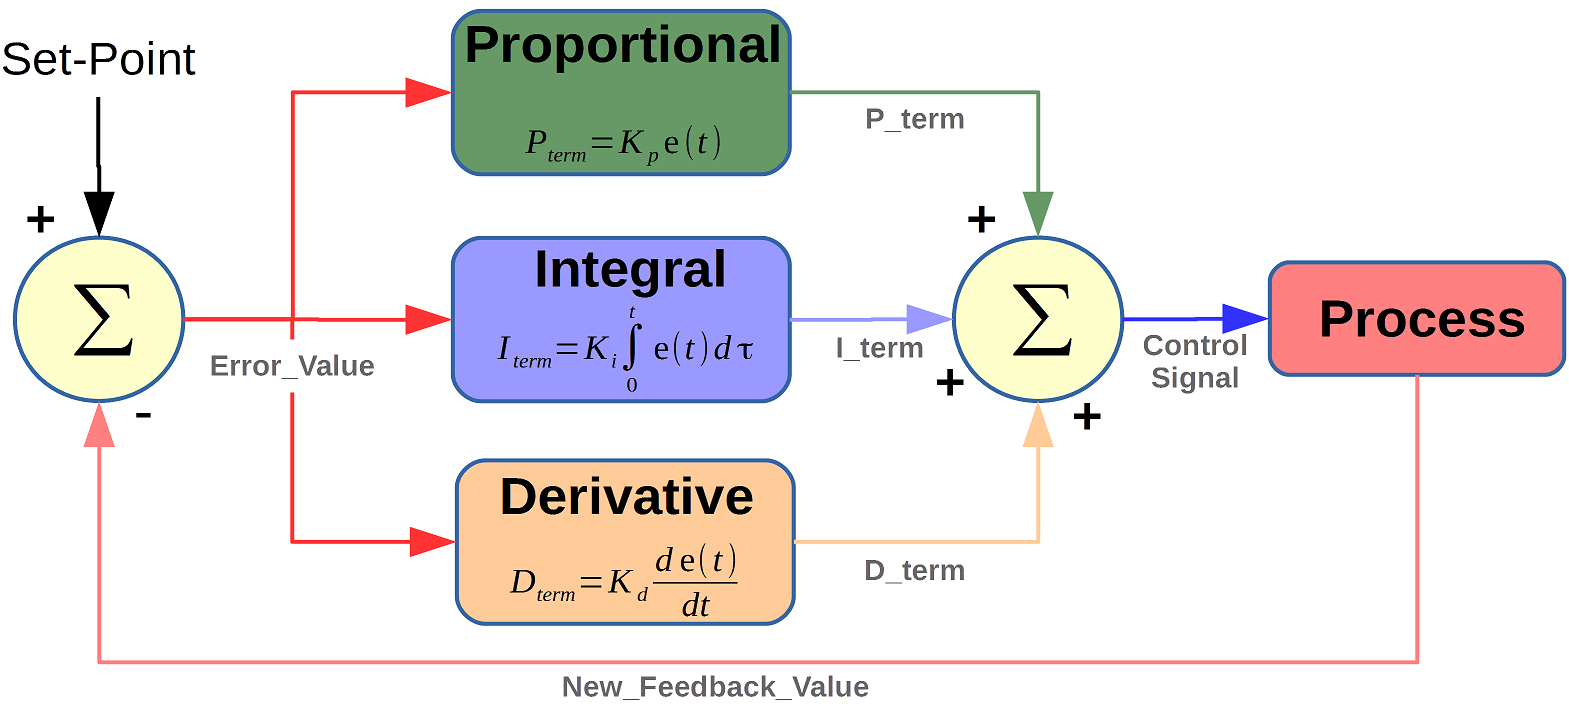

We will try to understand the function of each term and the consequence of their implementation on the system response.

### P control

As seen in previous equation, the proportional controller only has a constant term $K_p$. We will try for different value of $K_p$ and observe the response of the system.

Kp = 1;      % definition of Kp values
figure; hold;   % plot graph of step response

Current plot held


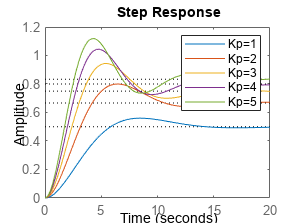


for i = 1:5     % Kp value 1 to 10
    C = pid(Kp);
    Kp = Kp + 1;
    sys_cl_Kp = feedback(C * G_MassSpring, 1); %implementation of feedback control
    step(sys_cl_Kp,t)       % step response

    % Performance criteria 
    y = step(sys_cl_Kp,t);
    y_ss(Kp) = y(end);  % Steady-state value is the final value of the response
    Overshoot(Kp) = (max(y) - y_ss) / y_ss * 100;  % Overshoot as a percentage
    % Calculate rise time (time to reach 90% of the steady-state value)
    tolerance = 0.10;
    idx_rise = find(y >= (1 - tolerance) * y_ss, 1);
    rise_time(Kp) = t(idx_rise);
end

% Plot graph of step response
legend('Kp=1','Kp=2','Kp=3','Kp=4','Kp=5')

**Reflections**

- For the range of value of Kp chosen in the code above,  compare the criteria of performance. How does Kp influence them? (The following code may be used to assist you)

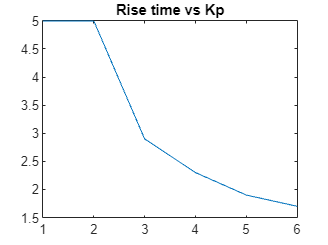

figure; plot(rise_time); title('Rise time vs Kp');

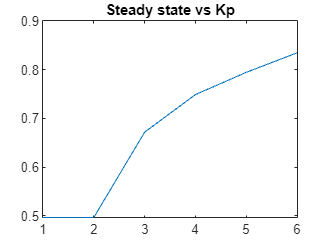

figure; plot(y_ss); title('Steady state vs Kp');

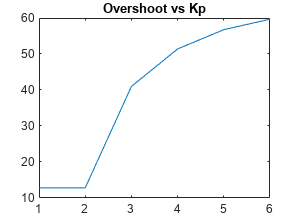

figure; plot(Overshoot); ; title('Overshoot vs Kp');

From the test above, we can see that the variation of the Kp value have the following consequence:

- decreasing the steady state error

- increasing the overshoot (for an underdamped system)

- reducing the rise time

In general, the proportional controller Kp is used to accelerate the response of a system (by reducing the rise time). Consequently, it may decrease the steady state error but, increase the overshooot. 

#### **Disturbance**

A control system is especially implemented to overcome disturbance. Here, we will try to add a disturbance to the system and observe teh response. The disturbance he is in the form of step input with amplitude 1. 

% Defintition of system with disturbance (C becomes feedback, refer to block diagram)
Kp = 1;     %reset for Kp = 1

dist_cl = feedback(G_MassSpring,Kp);
step(dist_cl)
% In comparison with no disturbance
hold

Current plot held


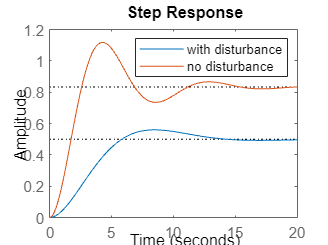

step(sys_cl_Kp,t)
legend('with disturbance','no disturbance')

**Reflections**

- Observe and describe the difference between the response of the system without and with disturbance.

- Despite having Kp, what cannot be accomplished by the proportional controller?

### PI control

The PI controller add the Integrator term $K_i$ to the controller. Unlike the proportional controller, $K_i$ is not a constant value. It is multiplied by the integral of the error $e$, making the total controller terms as $K_p +K_i \int_0^t e\left(t\right)\ldotp \mathrm{dt}$  . We recall that $e$ is the error which is the difference between the input and output at any time $t$.

Let's see the consequence of implementing a PI controller to our mass spring system. 

Kp = 5;      % definition of Kp values
Ki = 0.1;   % initial value Ki
figure; hold;   % plot graph of step response

Current plot held


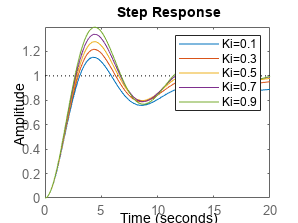


for i = 1:5     % Ki value 1 to 10
    C = pid(Kp,Ki);
    Ki = Ki + 0.2;
    sys_cl_KpKi = feedback(C * G_MassSpring, 1); %implementation of feedback control
    step(sys_cl_KpKi,t)       % step response

    % Performance criteria 
    y = step(sys_cl_KpKi,t);
    y_ss(i) = y(end);  % Steady-state value is the final value of the response
    Overshoot(i) = (max(y) - y_ss) / y_ss * 100;  % Overshoot as a percentage
    % Calculate rise time (time to reach 90% of the steady-state value)
    tolerance = 0.10;
    idx_rise = find(y >= (1 - tolerance) * y_ss, 1);
    rise_time(i) = t(idx_rise);
end

% Plot graph of step response
legend('Ki=0.1','Ki=0.3','Ki=0.5','Ki=0.7','Ki=0.9')

As usual, we extract then the performance criteria of the system:

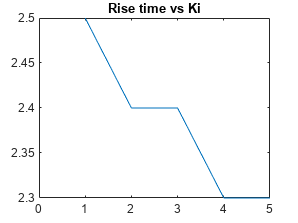

figure; plot(rise_time); title('Rise time vs Ki'); xlim([0,5]);

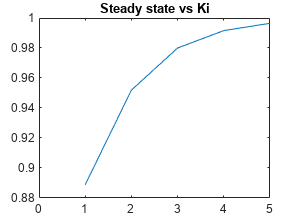

figure; plot(y_ss); title('Steady state vs Ki'); xlim([0,5]);

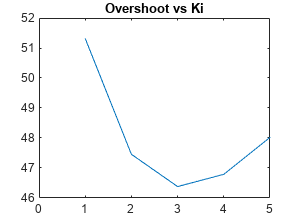

figure; plot(Overshoot); title('Overshoot vs Ki'); xlim([0,5]);

**Reflections**

- For the range of value of Ki chosen in the code above,  compare the criteria of performance. How does Ki influence them?

In general, the Kp terms added to the PI controller has the additional effect of **reducing the steady state error**. 

### PID control

The PID controller add the Derivaqtor term $K_d$ to the controller. $K_d$ is multiplied by the derivative of the error $e$, making the total controller terms as $K_p +K_i \int_0^t e\left(t\right)\ldotp \mathrm{dt}+K_d \frac{\mathrm{de}\left(t\right)}{\mathrm{dt}}$  . We recall that $e$ is the error which is the difference between the input and output at any time $t$.

Let's see the consequence of implementing a PI controller to our mass spring system. 

Kp = 5;      % definition of Kp value
Ki = 0.9;       % definition of Ki value
Kd = 0;      % initial value Kd
figure; hold;   % plot graph of step response

Current plot held


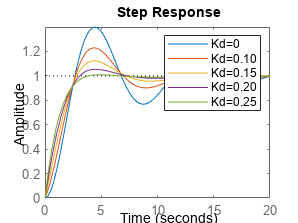


for i = 1:5;
    C = pid(Kp,Ki,Kd);
    Kd = Kd + 2;
    sys_cl_KpKiKd = feedback(C * G_MassSpring, 1); %implementation of feedback control
    step(sys_cl_KpKiKd,t)       % step response

    % Performance criteria 
    y = step(sys_cl_KpKiKd,t);
    y_ss(i) = y(end);  % Steady-state value is the final value of the response
    Overshoot(i) = (max(y) - y_ss) / y_ss * 100;  % Overshoot as a percentage
    % Calculate rise time (time to reach 90% of the steady-state value)
    tolerance = 0.10;
    idx_rise = find(y >= (1 - tolerance) * y_ss, 1);
    rise_time(i) = t(idx_rise);
end

% Plot graph of step response
legend('Kd=0','Kd=0.10','Kd=0.15','Kd=0.20','Kd=0.25')

As usual, we extract then the performance criteria of the system:

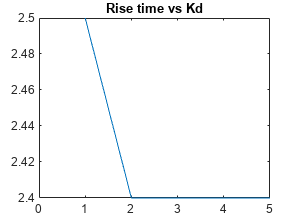

figure; plot(rise_time); title('Rise time vs Kd'); xlim([0,5]);

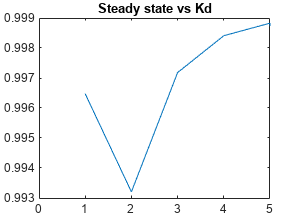

figure; plot(y_ss); title('Steady state vs Kd'); xlim([0,5]);

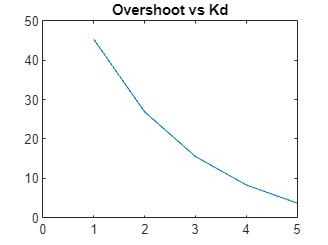

figure; plot(Overshoot); title('Overshoot vs Kd'); xlim([0,5]);

**Reflections**

- For the range of value of Kd chosen in the code above,  compare the criteria of performance. How does Kd influence them?

In general, the Kd terms added to the PID controller has the additional effect of **reducing the overshoot**.

## Conclusion 

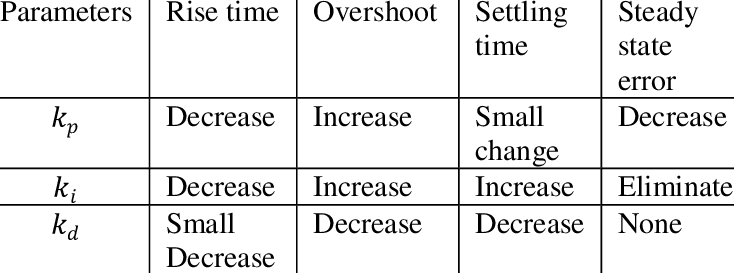

For our system of mass spring, the final parameter for the PID controller are:

- Kp = 5

- Ki = 0.9

- Kd = 0.25

This values gives a final response of:

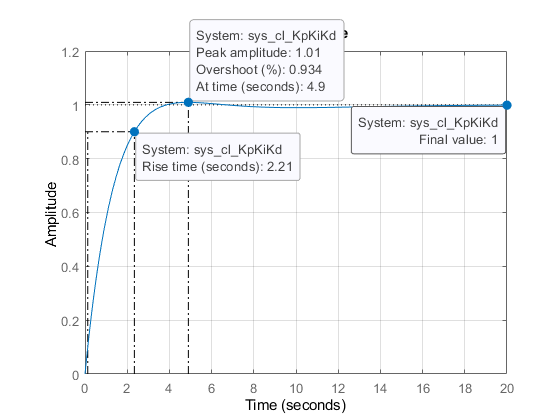

These performance criteria are considered good in comparison to the initial response. Comparing them, we have:

% Inital system response
M = 10;         % mass in kg
b = 5;        % viscuous friction in N/m/s^2
k = 1;         % spring elasticy in N/m
s = tf('s');
G_MassSpring = 1/(M*s^2 + b*s + k);  
sys_cl = feedback(G_MassSpring,1)   % closed loop TF

sys_cl =
 
         1
  ----------------
  10 s^2 + 5 s + 2
 
Continuous-time transfer function.



t = 0:0.1:20;
step(sys_cl,t)
hold

Current plot held


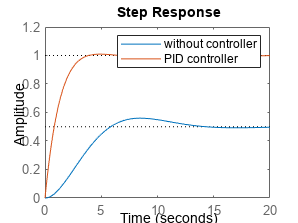


% Response with tuned PID.
sys_cl_KpKiKd = feedback(C * G_MassSpring, 1); %implementation of feedback control
step(sys_cl_KpKiKd,t) 
legend('without controller','PID controller')

The method that we use here to choose the gain of PID is called **heuristic method or try and error**. However, a more efficient method exist and we will learn it in the next chapter.